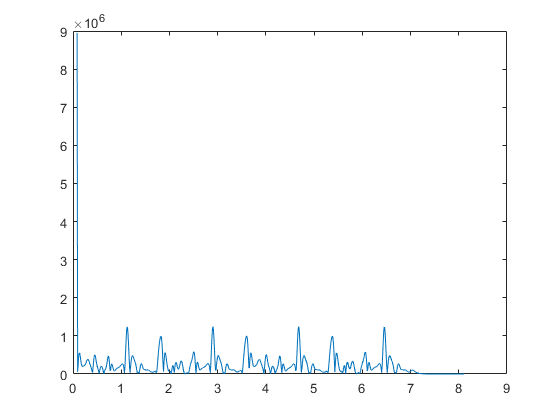

newTime =     0.0853    0.0960    0.1067    0.1173    0.1280    0.1387    0.1493    0.1600    0.1707    0.1813    0.1920    0.2027    0.2133    0.2240    0.2347    0.2453    0.2560    0.2667    0.2773    0.2880    0.2987    0.3093    0.3200    0.3307    0.3413    0.3520    0.3627    0.3733    0.3840    0.3947    0.4053    0.4160    0.4267    0.4373    0.4480    0.4587    0.4693    0.4800    0.4907    0.5013    0.5120    0.5227    0.5333    0.5440    0.5547    0.5653    0.5760    0.5867    0.5973    0.6080


HFCDiff = 	1.0e+06 *

    8.9514    0.0562    0.2436    0.4512    0.5480    0.5470    0.4729    0.3739    0.2829    0.2241    0.1956    0.1923    0.2046    0.2119    0.2224    0.2346    0.2547    0.2857    0.3215    0.3559    0.3766    0.3830    0.3683    0.3365    0.2972    0.2545    0.2145    0.1744    0.1323    0.0670    0.0363    0.1741    0.3226    0.4424    0.5037    0.4954    0.4317    0.3456    0.2667    0.2083    0.1640    0.1179    0.0573    0.0224    0.0981    0.1594    0.1974    0.2087    0.1965    0.1666


wav = 'AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav';

FFTSize = 8192;
hopSize = 512;
[newTime,HFCDiff] = Noctones_HFCDiff(wav,FFTSize,hopSize)

realLocsResized =     35    62    98   126   265   292   369   395   432   459   598   626


peaksPos =      0     0     0     0     0     0     0     0     0     0     0     0


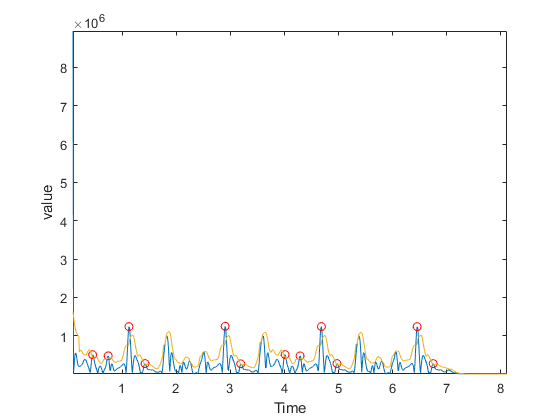

peaks =     0.4480    0.7360    1.1200    1.4187    2.9013    3.1893    4.0107    4.2880    4.6827    4.9707    6.4533    6.7520


peaks = Noctones_FindPeaks(newTime,HFCDiff,20)

[RMSTab,events] = Noctones_RMS(wav, FFTSize,hopSize)

Computing miraudio related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...
Computing mirsum related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...
Elapsed time is 0.190393 seconds.
Computing mirrms related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...
Computing mironsets related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...
Computing mirsum related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...
Computing mirpeaks related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...


RMSTab =     0.0677    0.0689    0.0699    0.0710    0.0713    0.0712    0.0707    0.0688    0.0672    0.0652    0.0637    0.0620    0.0601    0.0590    0.0573    0.0557    0.0541    0.0524    0.0503    0.0479    0.0461    0.0438    0.0416    0.0394    0.0371    0.0346    0.0322    0.0338    0.0343    0.0350    0.0361    0.0376    0.0400    0.0425    0.0455    0.0480    0.0502    0.0527    0.0549    0.0567    0.0583    0.0599    0.0610    0.0606    0.0608    0.0609    0.0609    0.0604    0.0598    0.0586


events =     0.0454
    0.4506
    0.7290
    1.1175
    1.2367
    1.3424
    1.8232
    2.3018
    2.5097
    2.8960


[pks,locs] = findpeaks(RMSTab,'MinPeakDistance',10)

pks =     0.0713    0.0610    0.0589    0.0673    0.0601    0.0723    0.0609    0.0467    0.0606    0.0672    0.0599    0.0370    0.0723    0.0609    0.0590    0.0672    0.0599    0.0391    0.0719    0.0609    0.0587    0.0464    0.0604    0.0673    0.0601


locs =      5    43    69   106   127   172   183   217   236   273   294   319   339   379   403   439   460   487   504   516   527   550   569   606   627


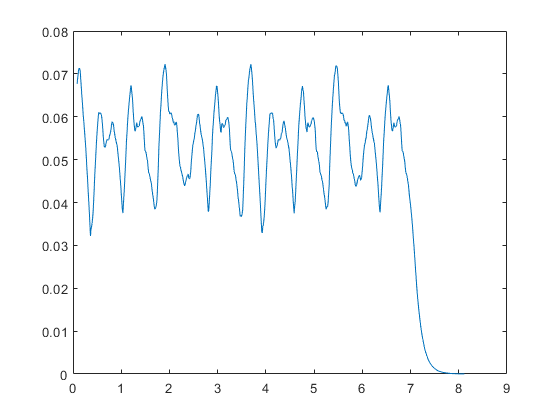

plot(newTime,RMSTab)

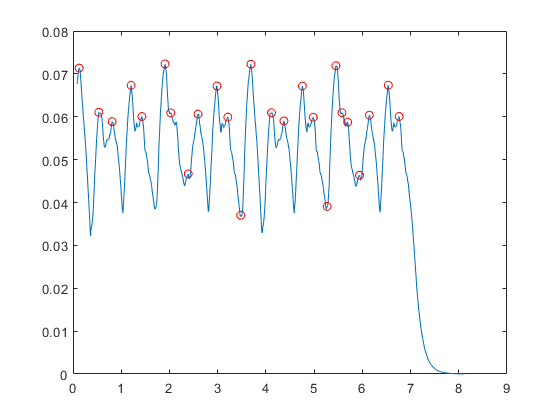

plot(newTime,RMSTab,newTime(locs),pks,'or')